start mosek
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 1.819232e+01 0.005575
post obj = 4.011699e+00, err = 1.010685e-01, 1.210718e+00, margin = 1.191683e+00, 6.480054e-01, s = 1.000000e+00, 1.000000e+00, post_s = 1.000000e+00, 1.411979e+00
    0.0056

mgn  1.191683	0.688114	0.648005
s    1.000000	1.411979	1.000000
r    1.325165	 2.111927	12.656635


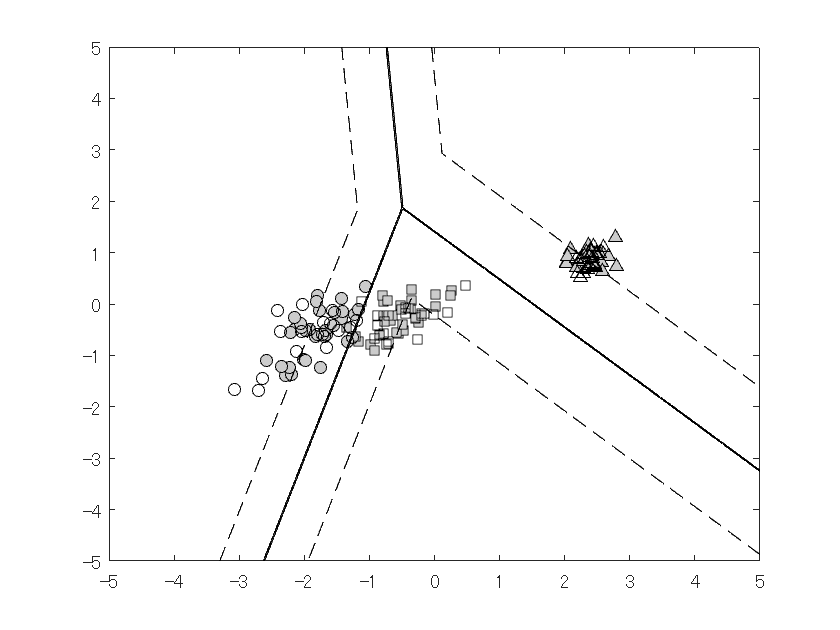

load data/iris_orig.mat
% load data/wine_orig.mat
% load data/balance-scale_orig.mat

T = T_100ratio60_10cv5;
Tk = T{3};
t = (Tk.train==1);
t = double(t');

sigma = 2^8;

proj = RBF_PCA(X,sigma,200);
X = proj(X)*sigma;

param.lambda = 1e-0;
param.alpha = 2;

param.is_s_fixed = true;
svm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,svm);

start mosek
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 1.549619e+01 0.004728
post obj = 3.726611e+00, err = 8.162172e-02, 1.289543e+00, margin = 1.130018e+00, 5.579021e-01, s = 1.000000e+00, 2.885169e+00, post_s = 1.000000e+00, 2.885169e+00
    0.0047

mgn  1.045571	1.130018	0.557902
s    1.000000	2.885169	1.000000
r    1.033162	 0.853267	12.001202


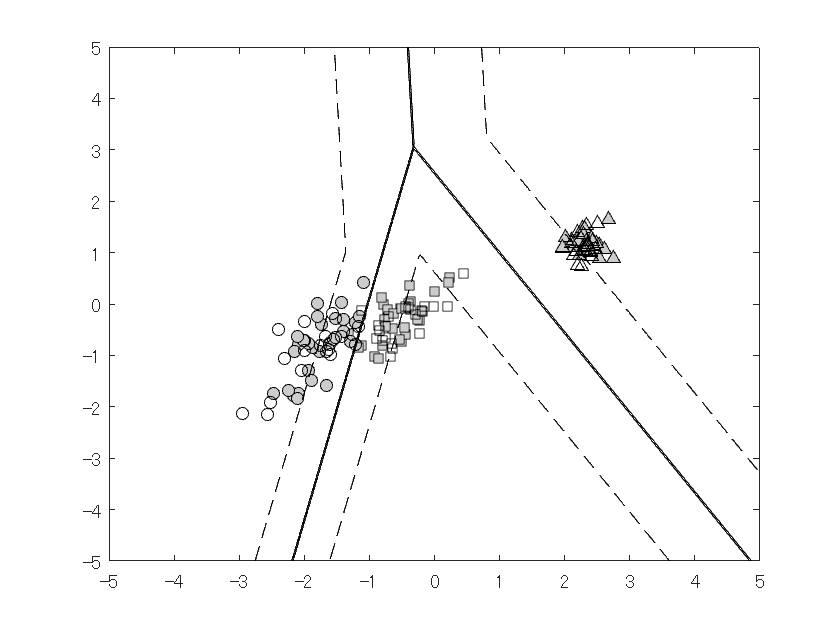


param.is_s_fixed = false;
svm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,svm);

start mosek
MSK_RES_TRM_STALL OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 3.634879e+01 0.005978
post obj = 5.134436e-01, err = 2.019378e-03, 1.796099e-01, margin = 8.761868e-02, 2.355264e-02, s = 1.000000e+00, 1.000000e+00, post_s = 1.000000e+00, 2.943902e+00
    0.0060

mgn  0.063815	0.087619	0.023553
s    1.000000	2.943902	1.000000
r    0.024560	0.013026	0.226039


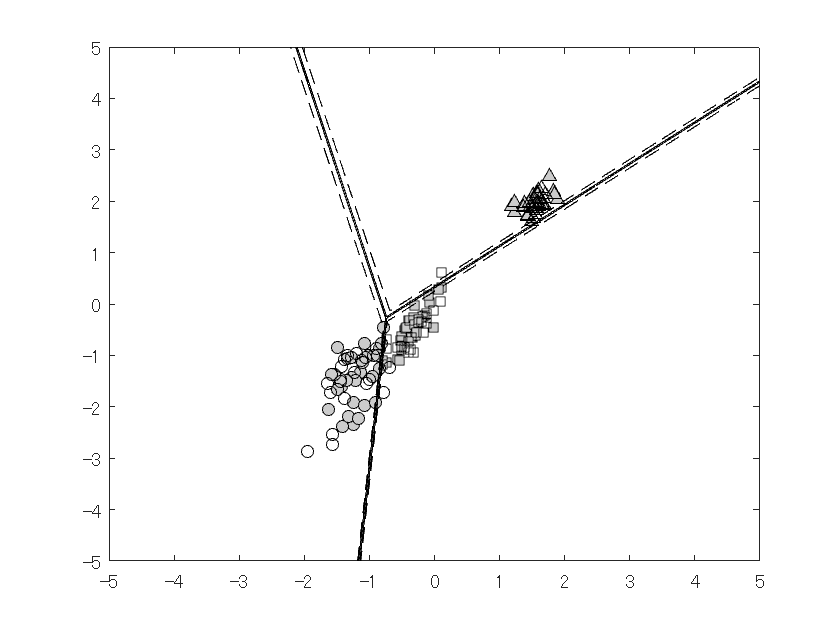


param.lambda = 1e-2;
param.alpha = 2;

param.is_s_fixed = true;
svm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,svm);

start mosek
MSK_RES_TRM_STALL UNKNOWN UNKNOWN 2.273719e+01 0.008414
post obj = 4.671352e-01, err = 1.237745e-03, 1.113605e-01, margin = 8.614166e-01, 2.233507e-02, s = 1.000000e+00, 4.899653e+01, post_s = 1.000000e+00, 4.899654e+01
    0.0084

mgn  0.828833	0.861417	0.022335
s    19.466324	48.996537	 1.000000
r    0.000146	0.000135	0.217935


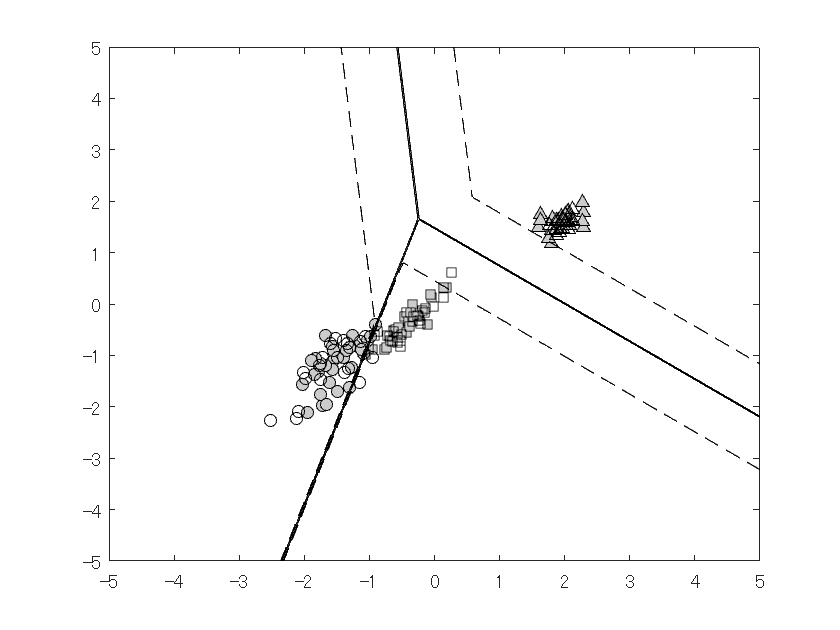


param.is_s_fixed = false;
svm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,svm);

function plot_boundary(X,lX,t,svm)

[W,b,res] = svm(X(:,t==1),lX(t==1));

disp(res.msk_time);

c = size(W,2);
m = size(X,2);

mgn = res.margin;
s = res.post_s;
r = res.post_r;

disp(['mgn  ',num2str(mgn,'%f\t')]);
disp(['s    ',num2str(s,'%f\t')]);
disp(['r    ',num2str(r,'%f\t')]);

W = W - mean(W,2)*ones(1,c);

[U,S,~] = svds(W,2);

Y = U'*X;
V = U'*W;

% R = [flip*cos(theta),-sin(theta);flip*sin(theta),cos(theta)];
% Y = Y*R';
% U = U*R';

figure;
hold on;
box on;

scatter(Y(1,lX==1&t==1),Y(2,lX==1&t==1),'k^','MarkerFaceColor',[.8,.8,.8]);
scatter(Y(1,lX==2&t==1),Y(2,lX==2&t==1),'ks','MarkerFaceColor',[.8,.8,.8]);
scatter(Y(1,lX==3&t==1),Y(2,lX==3&t==1),'ko','MarkerFaceColor',[.8,.8,.8]);

scatter(Y(1,lX==1&t==0),Y(2,lX==1&t==0),'k^');
scatter(Y(1,lX==2&t==0),Y(2,lX==2&t==0),'ks');
scatter(Y(1,lX==3&t==0),Y(2,lX==3&t==0),'ko');

f = @(x,y) margin(x,y,V,b);
fcontour(f,'k-','LevelList',[1e-2],'MeshDensity',800);

f = @(x,y) score(x,y,V,b,s);
fcontour(f,'k--','LevelList',[1],'MeshDensity',400);

end

function f = score(x,y,W,b,s)
c = size(W,2);
S = zeros(c);
S(tril(ones(c),-1)==1) = s;
S = S + S' + eye(c);
f = zeros(size(x));
for i=1:numel(x)
    F = W(1,:)*x(i) + W(2,:)*y(i) + b;
    [~,I] = sort(F,'descend');
    FF = -(F(I) - F(I(1)))./S(I,I(1))';
    FF2 = mink(FF,2);
    f(i) = FF2(end);
end
end

function f = margin(x,y,W,b)
f = zeros(size(x));
for i=1:numel(x)
    F = W(1,:)*x(i) + W(2,:)*y(i) + b;
    [~,I] = sort(F,'descend');
    f(i) = (F(I(1)) - F(I(2)))/(norm(W(:,I(1))-W(:,I(2))));
end
end
